# Power flow simulation

The purpose of this notebook is to assess the damage a wrong admittance matrix Y can make to a microgrid.

## Grid definition

Parameters for the grid are:

- the Laplacian admittance matrix Y

- the load paramenters Il, Pl and Yl

clear all
close all

Il_bar = [1, 1]';

Y =      3     0    -2    -1
     0     2    -1    -1
    -2    -1     3     0
    -1    -1     0     2


Yl_bar = [1, 1]';
Pl_bar = [1, 1]';
Y = [3 0 -2 -1; 0 2 -1 -1; -2 -1 3 0; -1 -1 0 2]

## Optimization problem

The optimization problem deals with the translation of power required from the generators into voltage signals. Constraints are imposed by the power flow equations as well as the positivity of generator power and voltages.

We assume to use a different Y matrix from the real one.

Pg_bar = [20 20]';
x0.Vg = [1 1]';
x0.Vl = [1 1]';
x0.Pg = [1 1]';

real_measures = [];
hat_measures = [];
perturbed_element = [1, 3];
deltas = linspace(-2, 2, 50);

for i=1:length(deltas)
    Y_hat = update_admittance(Y, perturbed_element(1), perturbed_element(2), deltas(i));
    [Vl_hat, Vg_real, Pg_hat] = power_to_voltages(Y_hat, Il_bar, Yl_bar, Pl_bar, Pg_bar, x0);
    Vl = sym('Vl', [2, 1]);
    Pg = sym('Pg', [2, 1]);
    Vl_real = vpasolve(fl_linear(Vg_real, Vl, Il_bar, Yl_bar, Pl_bar, Y) == 0, Vl);
    Vl_real = [double(Vl_real.Vl1), double(Vl_real.Vl2)]';
    Pg_real = vpasolve(fg(Vg_real, Vl_real, Pg, Y) == 0, Pg);
    Pg_real = [double(Pg_real.Pg1), double(Pg_real.Pg2)]';
    Ig_real = Y(1:2, 1:2) * Vg_real + Y(1:2, 3:4) * Vl_real;
    Il_real = Y(1:2, 3:4) * Vg_real + Y(3:4, 3:4) * Vl_real; 
    real_measures(i, :) = [Vl_real' Pg_real'];
    hat_measures(i, :) = [Vl_hat' Pg_hat'];
end


Solving problem using fmincon.

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Solving problem using fmincon.

Local minimum possible. Constraints satisfied.

fmincon stopped beca

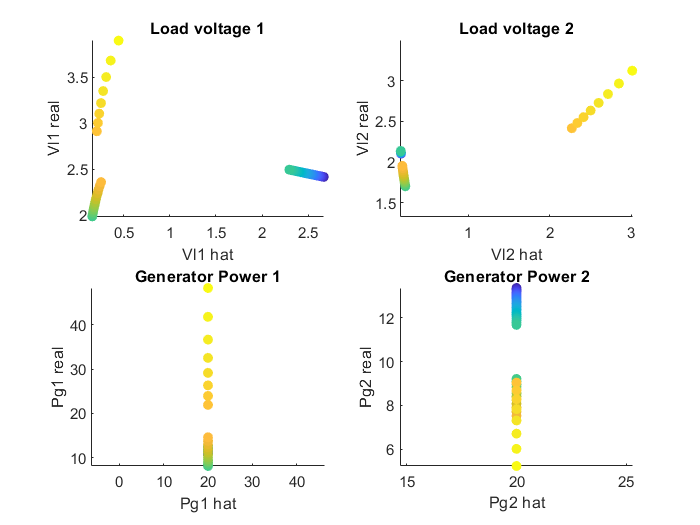

subplot(2,2,1);
scatter(hat_measures(:, 1), real_measures(:, 1), [], deltas', 'filled')
title('Load voltage 1')
xlabel('Vl1 hat')
ylabel('Vl1 real')
axis equal
subplot(2,2,2);
scatter(hat_measures(:, 2), real_measures(:, 2), [], deltas', "filled")
title('Load voltage 2')
xlabel('Vl2 hat')
ylabel('Vl2 real')
axis equal
subplot(2,2,3);
scatter(hat_measures(:, 3), real_measures(:, 3), [], deltas', "filled")
title('Generator Power 1')
xlabel('Pg1 hat')
ylabel('Pg1 real')
axis equal
subplot(2,2,4);
scatter(hat_measures(:, 4), real_measures(:, 4), [], deltas', "filled")
title('Generator Power 2')
xlabel('Pg2 hat')
ylabel('Pg2 real')
axis equal

% colorbar